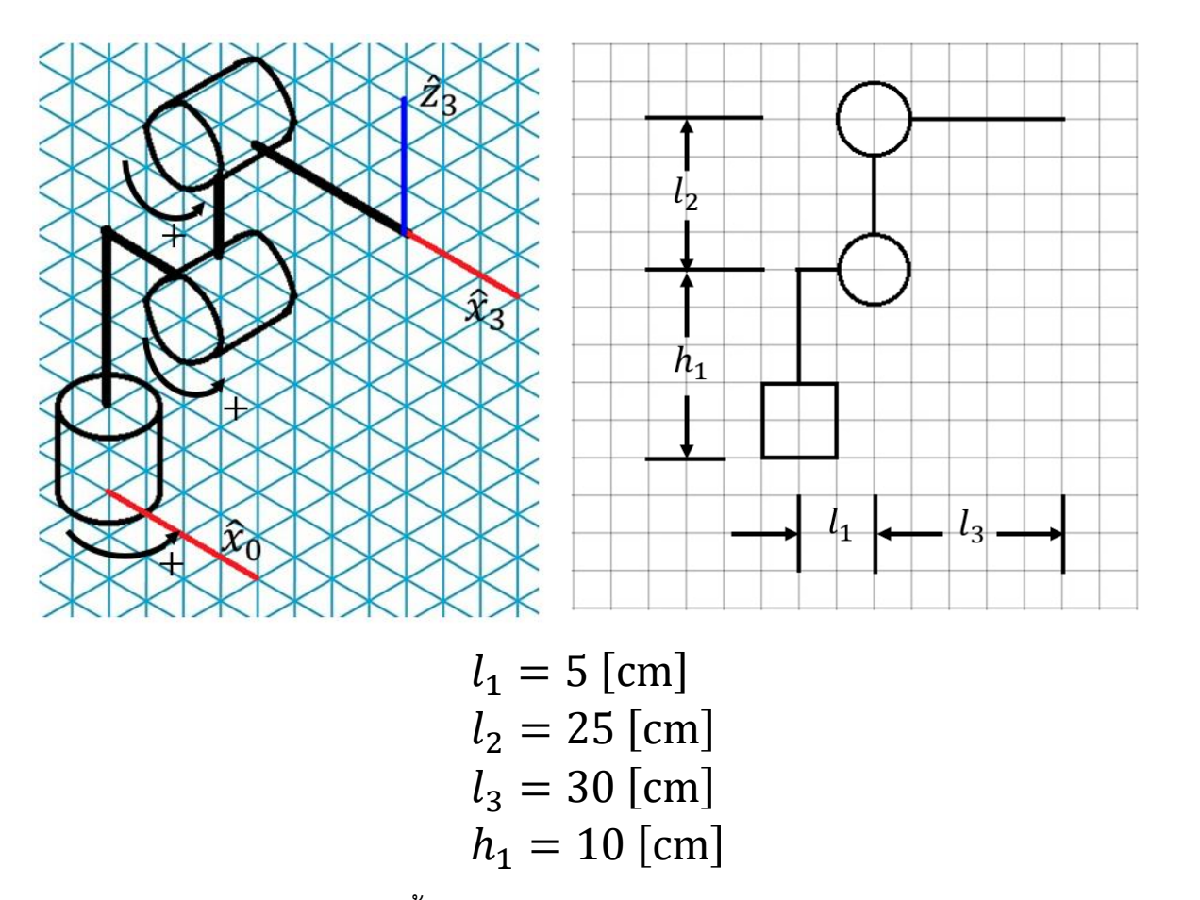                                                                                                                                                                                                                                

**input**

    .txt:    robot command = (2,n)

    .txt:    via_point_info = (3,m) // m = size of command via_points_task set in task space

**local variable**

    command = (1,n) L:0,J:1 

    via_point_task = (3,n) 

    via_point_joint_all = (3,n,4)

    via_point_joint = (3,n)

**step(function)**

readVariable => task2jointConversion =>  select optimal joint => gen C

**readVariable:** write .txt + return: via_point_task = (3,n), command = (1,n) L:0,J:1 

      Description: read variable

**task2jointConversion:** third dimension = all possible via point in joint space + return alert 0: cant access, 1: accessable; via_point_joint (3x4) D3: possible joint, D4: No. input via_point task

      Description: check possible access + convert task to joint

[command, via_point_task_all] = readVariable();
[alert, via_point_joint] = task2jointConversion(via_point_task_all)

alert =      1     1     1     1


via_point_joint = via_point_joint(:,:,1,1) =

         0
   -1.7521
    3.1416


via_point_joint(:,:,2,1) =

     0
     0
     0


via_point_joint(:,:,3,1) =

   -3.1416
    0.4148
    2.6561


via_point_joint(:,:,4,1) =

   -3.1416
    1.6096
    0.4855


via_point_joint(:,:,1,2) =

         0
   -1.5867
    1.7453


via_point_joint(:,:,2,2) =

         0
   -1.3963
    1.3963


via_point_joint(:,:,3,2) =

     0
     0
     0


via_point_joint(:,:,4,2) =

     0
     0
     0


via_point_joint(:,:,1,3) =

         0
   -0.8607
    2.3562


via_point_joint(:,:,2,3) =

         0
         0
    0.7854


via_point_joint(:,:,3,3) =

     0
     0
     0


via_point_joint(:,:,4,3) =

     0
     0
     0


via_point_joint(:,:,1,4) =

    3.1416
   -0.8607
    2.3562


via_point_joint(:,:,2,4) =

    3.1416
         0
    0.7854


via_point_joint(:,:,3,4) =

     0
     0
     0


via_point_joint(:,:,4,4) =

     0
     0
     0
